# [Imbalanced Data and Learning](https://apmonitor.com/pds/index.php/Main/ImbalancedData)

Imbalanced data is a disproportionate number of data points with discrete labels and can be a big challenge to develop an accurate classifier. A classifier attempts to find the data boundary where one class ends and the other begins. [**Classification**](https://apmonitor.com/pds/index.php/Main/ClassificationOverview) is used to create these boundaries when the desired output (label) is discrete such as 0/1, Yes/No, 1,2,3,4,5, or Normal/Abnormal. Regression is used when the desired output (label) is continuous.

Imbalanced data can give biased predictions for classification when there is a minority class. This tutorial demonstrates how to deal with imbalanced data.

**Download the tables and change the readtable function input to fit your needs.**

# **Change the file address to be more generic**

%create balanced data
T = readtable('C:/Users/jacob/OneDrive - Brigham Young University/Winter 2023 - Senior/ChEn461 - Problem Solving/MATLAB/Balanced_Data.xlsx')

T = 4000×3 table
       X          Y       label
    _______    _______    _____

     7.7574     4.1443      1  
    -4.8757    -1.4821      0  
    -4.5482     2.4708      0  
    -1.1726     5.8463      0  
    -2.8745    0.49394      0  
     6.4396      6.851      1  
     4.0846     6.2339      1  
     5.6163      2.066      1  
    -9.1604     3.9382      0  
     8.4615     1.4392      1  
    -1.6242     6.4938      0  
     3.6466     3.8637      1  
    -2.8658     2.0771      0  
      3.621     2.7725      1  
    -6.2231     1.1858      0  
     10.217     5.1664      1  


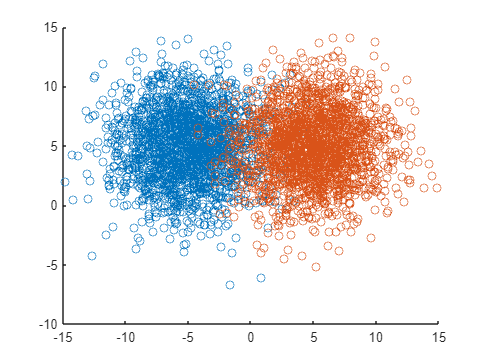


%Plot the data 
for cv = 0:1
    row = find(T.("label") == cv);
    scatter(T.X(row,1),T.Y(row,1))
    hold on
end 

hold off

The dots are the color of the respective label. In this example, each class has the same size and spread and the the classifier splits the space in the middle. However, many data sets are imbalanced where every class is unequally sized, or *weighted*. This imbalance skews the classifier to favor the majority class.

#### Equal sets of Data

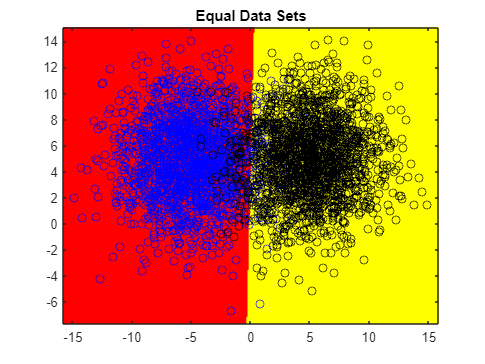

%%Logistic Regression 
model = fitclinear([T.X,T.Y], T.label);

% Find minimums and maximums of X and Y
maxX = max(T.X) + 1;
minX = min(T.X) - 1;
maxY = max(T.Y) + 1;
minY = min(T.Y) - 1;

% Create a grid
x1grid = (minX:0.1:maxX);
x2grid = (minY:0.1:maxY);
[xx, yy] = meshgrid(x1grid,x2grid);
grid = [xx(:),yy(:)];

% Use grid and model to predict y
yp = predict(model,grid);
zz = reshape(yp,size(xx));

% Plot a contour map of the predicted values
contourf(xx,yy,zz,'LineStyle','none');
colormap(autumn)
hold on

%Plot the data onto the contour map
for cv = 0
    row = find(T.("label") == cv);
    scatter(T.X(row,1),T.Y(row,1),"blue")
    hold on
end 

for cv = 1
    row = find(T.("label") == cv);
    scatter(T.X(row,1),T.Y(row,1),"black")
    hold on
end 
title('Equal Data Sets')   
hold off

#### Unequal Data

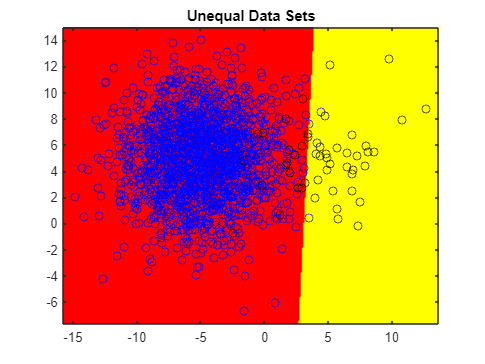

% Read data
U = readtable('C:/Users/jacob/OneDrive - Brigham Young University/Winter 2023 - Senior/ChEn461 - Problem Solving/MATLAB/Undersample_Data.xlsx');

%%Logistic Regression 
model = fitclinear([U.X,U.Y], U.label,'Learner','logistic');

% Find minimums and maximums of X and Y
maxX = max(U.X) + 1;
minX = min(U.X) - 1;
maxY = max(U.Y) + 1;
minY = min(U.Y) - 1;

% Create a grid
x1grid = (minX:0.1:maxX);
x2grid = (minY:0.1:maxY);
[xx, yy] = meshgrid(x1grid,x2grid);
grid = [xx(:),yy(:)];

% Use grid and model to predict y
yp = predict(model,grid);
zz = reshape(yp,size(xx));

% Plot a contour map of the predicted values
contourf(xx,yy,zz,'LineStyle','none');
colormap(autumn)
hold on

%Plot the data onto the contour map
for cv = 0
    row = find(U.("label") == cv);
    scatter(U.X(row,1),U.Y(row,1),"blue")
    hold on
end 

for cv = 1
    row = find(U.("label") == cv);
    scatter(U.X(row,1),U.Y(row,1),"black")
    hold on
end 
title('Unequal Data Sets')
hold off

As the orange class has a smaller sampling, the classifier moves the boundary to the right. With 2000 samples of blue and 50 samples of orange, the boundary is shifted 3 units to the right and misclassifies the orange minority class.

## Undersample Majority Class

One way to deal with a much larger class is to undersample. This removes random instances from the majority class to reduce the number of instances to be comparable to the other classes. There are a few limitations to this. If the majority class is not sufficiently large, undersampling may lead to too little data overall for the model fit or validation. If the majority class samples are not normally distributed, stochastic undersampling can misshape the class, leading to additional errors. These factors should be considered before the decision to undersample. There is an improvement with undersampling the majority class in the synthetic data set.

### Under Sampling

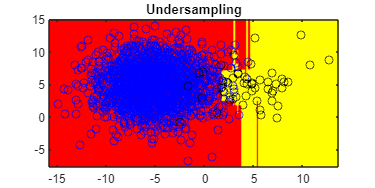

% Undersample Part 2
pipeline = fitcensemble([U.X,U.Y], U.label, 'Method', 'RUSBoost');
yp = predict(pipeline, grid);
zz = reshape(yp, size(xx));
figure('Units', 'inches', 'Position', [0, 0, 6, 3]);
contourf(xx, yy, zz, 'LineStyle', 'none');
colormap("autumn"); hold on;
for cv = 0
    row = find(U.label == cv);
    scatter(U.X(row, 1), U.Y(row, 1),'blue');
end
for cv = 1
    row = find(U.label == cv);
    scatter(U.X(row, 1), U.Y(row, 1),'black');
end
title('Undersampling')
hold off;

## Oversampling Minority Class

Oversampling is the opposite of undersampling. SMOTE (Synthetic Minority Oversampling Technique) is a method to oversample the minority class. SMOTE creates artificial sample points in the same area space as the minority class, allowing the model to weight the minority class and improve classifier accuracy. It must be noted, however, that these additional points are synthetic and if the minority class space is similar to that of another class, could lead to misclassification of other classes due to the expansion of the minority bounds in hyperspace.

Download the following package for SMOTE.

[Synthetic Minority Over-sampling Technique (SMOTE) - File Exchange - MATLAB Central (mathworks.com)](https://www.mathworks.com/matlabcentral/fileexchange/75401-synthetic-minority-over-sampling-technique-smote)

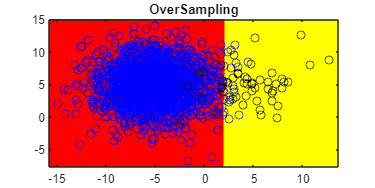

% Seperate data into the minority and majority
% Minority Class is label = 1
underX = U.X(U.label == 1);
underY = U.Y(U.label == 1);
under_label = U.label(U.label == 1);
% Majority  Class is label = 0
overX = U.X(U.label == 0);
overY = U.Y(U.label == 0);
over_label = U.label(U.label == 0);

% Create artificial data points with the minority class
sm_mod = smote([underX,underY,under_label],[,3]);

% Combine the majority class with the artifical minority class
newdata_X = cat(1,overX, sm_mod(:,1));
newdata_y = cat(1,overY,sm_mod(:,2));
newdata_label = cat(1,over_label,sm_mod(:,3));

% Create a linear classification fit of the New Data
model = fitclinear([newdata_X,newdata_y], newdata_label);

% Use grid and model to predict y
yp = predict(model,grid);
zz = reshape(yp,size(xx));

% Plot a contour map of the predicted values
contourf(xx,yy,zz,'LineStyle','none');
colormap(autumn)
hold on

%Plot the data onto the contour map
for cv = 0
    row = find(U.("label") == cv);
    scatter(U.X(row,1),U.Y(row,1),"blue")
    hold on
end 

for cv = 1
    row = find(U.("label") == cv);
    scatter(U.X(row,1),U.Y(row,1),"black")
    hold on
end 
    
title('OverSampling');
hold off

## Alternate Methods

Unsupervised learning methods such as K-means Clustering can train on the majority class and detect the minority class or classes as anomalies in the dataset. As an example, imagine a situation with four, similar-sized minority classes and one majority class where the majority class is much larger than the four minority classes. Anomaly detection, or binary classification, could be used to classify the data between “majority class” or “non-majority class”. A separate classifier could be trained on the “anomalous” data without the majority class. This subsequent model could then classify the data into any of the respective minority classes. This method can be chained and scaled to address imbalanced data.

## Conclusion

Oversampling and undersampling both adjust the training data to more accurately classify the minority class.

# Activity

The following imbalanced dataset has five features (inputs) and one label (output) with three classes (0,1,2).

 [**Imbalanced Train Data**](https://apmonitor.com/pds/uploads/Main/imbalanced_train.csv)

 [**Imbalanced Test Data**](https://apmonitor.com/pds/uploads/Main/imbalanced_test.csv)

The training set is undersampled from some true population, contained in the test set. Rebalance the training data to improve the classification of the minority class in the test set.

### Import Data with Weighted Classess

% Import data
Test = readtable('C:/Users/jacob/OneDrive - Brigham Young University/Winter 2023 - Senior/ChEn461 - Problem Solving/MATLAB/imbalanced_test.csv')

Test = 25251×6 table
     Var1        Var2       Var3      Var4      Var5     Var6
    _______    ________    ______    ______    ______    ____

          0           1         2         3         4    NaN 
     -11.18      2.0541    4.9439    7.9373    5.4048      0 
    -10.844      3.9195    4.8428    7.3774    7.3014      2 
     -11.76      2.8797    5.3302    5.6599    7.6934      2 
    -9.4819      5.3444    3.9703     4.318    6.0627      1 
    -8.8332      2.3421    7.1549    6.6623    6.7863      2 
    -11.247      2.0275     6.059    7.1212    5.2241      0 
    -8.0981      2.5759    4.1818    7.2544    7.0439      2 
    -9.7444      2.3928    4.6098    4.2249    5.9645      1 
    -9.0823      3.9987    3.1694    3.9576    5.3922      1 
    -12.941      2.4427    5.4

Train = readtable('C:/Users/jacob/OneDrive - Brigham Young University/Winter 2023 - Senior/ChEn461 - Problem Solving/MATLAB/imbalanced_train.csv')

Train = 1001×6 table
     Var1       Var2      Var3      Var4      Var5     Var6
    _______    ______    ______    ______    ______    ____

          0         1         2         3         4    NaN 
      -10.8    3.1728    5.2396    7.3072     5.994      0 
    -14.991    3.0176    3.9777    5.3609    4.7848      0 
    -11.718    1.4841     6.604     7.225    3.8768      0 
    -11.452     2.013    5.3012    7.6598    8.7345      2 
    -10.978    4.6769    6.5538    7.2339    4.5756      0 
    -12.326    2.7468    5.4533    4.6846    2.4295      0 
    -11.643    2.5352    5.9351    4.1138    5.9361      0 
    -12.642    3.9009    3.9635    5.5033    5.4064      0 
    -13.669    4.3034    5.7516    7.8943     4.446      0 
    -10.451    3.6212    4.8641     4.359    4.9316   

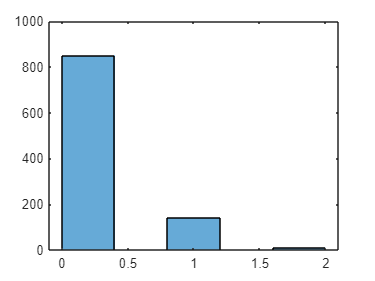


% delete frist row and name columns
Test(1,:) = [];
Train(1,:) = [];
Test.Properties.VariableNames = [0,1,2,3,4,"Label"];
Train.Properties.VariableNames = [0,1,2,3,4,"Label"];

% Histogram
figure;
histogram(Train.Label,5)

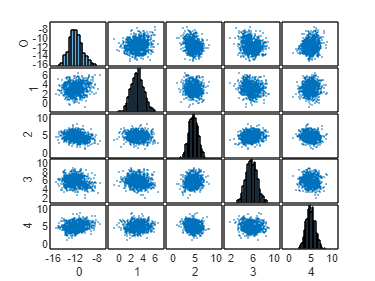


% Pairplot
figure;
[~,AX] = plotmatrix(table2array(Train(:,1:end-1)));
ylabel(AX(1,1),'O');
ylabel(AX(2,1),'1');
ylabel(AX(3,1),'2');
ylabel(AX(4,1),'3');
ylabel(AX(5,1),'4');
xlabel(AX(5,1),'0');
xlabel(AX(5,2),'1');
xlabel(AX(5,3),'2');
xlabel(AX(5,4),'3');
xlabel(AX(5,5),'4');

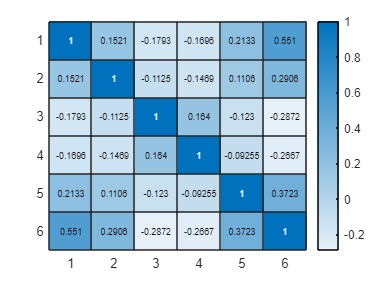


% Heatmap
corr = corrcoef(table2array(Train(:,1:end)));
figure;
heatmap(corr);

### Create ModelsMake One Model Weighted, and One Unweighted

In order to "weight" a model, there are several approaches one can take. Oversampling the minority classes or undersampling the majority classes is one way to try to "fill" imbalanced data. When oversampling minority classes, typically methods such as SMOTE are used. SMOTE creates artificial samples of a class with features within the vector space of the other class samples. Another approach, which is not shown here, is to use the "weights" kwarg that many model classes have. These accept some coefficient array that tells the model to adjust itself to compensate for imbalances. Reproportion the data to be the same quantity for each class by oversampling the minority and undersampling the majority.

% Split data into inputs and outputs for both the train and test data sets
Xtrain = Train(:,1:end-1);
Ytrain = Train.Label;
Xtest = Test(:,1:end-1);
Ytest = Test.Label;

% Determine which class is the smallest
fprintf('Size of 0: %.2f\n',length(Ytrain(Ytrain==0)))

Size of 0: 850.00


fprintf('Size of 1: %.2f\n',length(Ytrain(Ytrain==1)))

Size of 1: 140.00


fprintf('Size of 2: %.2f\n',length(Ytrain(Ytrain==2)))

Size of 2: 10.00


#### Oversample

% Split data into the minority and the two majority class with 2 being the

Oversample Method

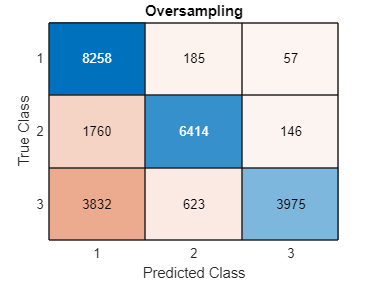

% minority class as shown above
underX = [Xtrain.("0")(Ytrain == 2),Xtrain.("1")(Ytrain == 2),Xtrain.("2")(Ytrain == 2),Xtrain.("3")(Ytrain == 2),Xtrain.("4")(Ytrain == 2)];
overX = [Xtrain.("0")(Ytrain ~= 2),Xtrain.("1")(Ytrain ~= 2),Xtrain.("2")(Ytrain ~= 2),Xtrain.("3")(Ytrain ~= 2),Xtrain.("4")(Ytrain ~= 2)];
under_label = Ytrain(Ytrain == 2);
over_label = Ytrain(Ytrain ~= 2);

% Create the artificial data points with the minority class
smmod = smote([underX,under_label],4);

% Combine the majority class with the artificial minority class 
nwdata = cat(1,overX,smmod(:,1:end-1));
nwdata_label = cat(1,over_label,smmod(:,end));

% Create a linear classification fit of the data
overmodel = fitcecoc(nwdata,nwdata_label);

% Create predicted label data
ypred = predict(overmodel,table2array(Xtest));

% Create the confusion chart of the oversampling
Cover = confusionmat(Ytest,ypred);
confusionchart(Cover)
title(['Oversampling'])


% Copyright (c) 2015, Audrey Cheong
% All rights reserved.
stats = confusionmatStats(Ytest,ypred);
fprintf('Fscore Class 0: %.2f\n',stats.Fscore(1))

Fscore Class 0: 0.74


fprintf('Fscore Class 1: %.2f\n',stats.Fscore(2))

Fscore Class 1: 0.83


fprintf('Fscore Class 2: %.2f\n',stats.Fscore(3))

Fscore Class 2: 0.63


#### Undersample

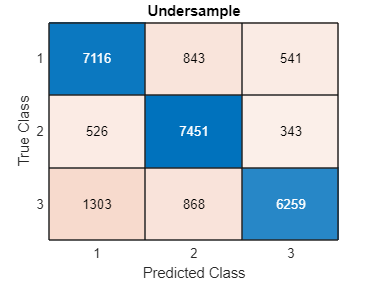

% Take the 20 samples from each group that are not the minority class
Xtrain1 = [Xtrain.("0")(Ytrain == 1),Xtrain.("1")(Ytrain == 1),Xtrain.("2")(Ytrain == 1),Xtrain.("3")(Ytrain == 1),Xtrain.("4")(Ytrain == 1)];
ranXtrain1 = datasample(Xtrain1,20,'Replace',false);
Xtrain0 = [Xtrain.("0")(Ytrain == 0),Xtrain.("1")(Ytrain == 0),Xtrain.("2")(Ytrain == 0),Xtrain.("3")(Ytrain == 0),Xtrain.("4")(Ytrain == 0)];
ranXtrain0 = datasample(Xtrain0,20,'Replace',false);

ranYtrain1 = datasample(Ytrain(Ytrain==1),20);
ranYtrain0 = datasample(Ytrain(Ytrain==0),20);

% Combine the randomly sampled data with the minority class
newdataX = cat(1,underX,cat(1,ranXtrain0,ranXtrain1));
newdataY = cat(1,under_label,cat(1,ranYtrain0,ranYtrain1));

% Create a linear classification fit of the data
pipeline = fitcecoc(newdataX,newdataY);

% Create predicted label data
ypredu = predict(pipeline,table2array(Xtest));

% Create the confusion chart of the undersampling
Cunder = confusionmat(Ytest,ypredu);
confusionchart(Cunder)
title('Undersample')


% Copyright (c) 2015, Audrey Cheong
% All rights reserved.
stats = confusionmatStats(Ytest,ypredu);
fprintf('Fscore Class 0: %.2f\n',stats.Fscore(1))

Fscore Class 0: 0.82


fprintf('Fscore Class 1: %.2f\n',stats.Fscore(2))

Fscore Class 1: 0.85


fprintf('Fscore Class 2: %.2f\n',stats.Fscore(3))

Fscore Class 2: 0.80
